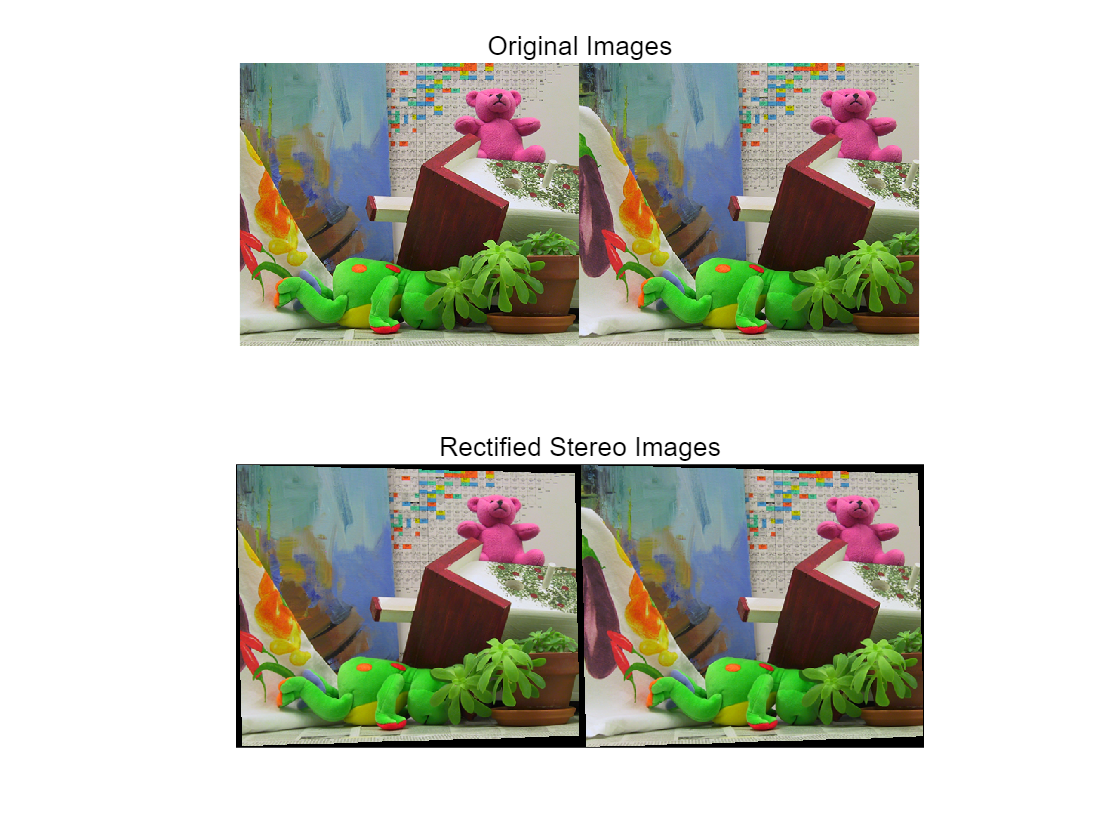

img1 = imread('left.png');
img2 = imread('right.png');

im1 = im2double(img1);
im2 = im2double(img2);

Po1 = double([976.5 53.82 -239.8 387500 
       98.49 933.3 157.4 242800
       .579 .1108 .8077 1118]);
Po2 = double([976.7 53.76 -240 40030
       98.68 931.0 156.71 251700
       .5766 .1141 .8089 1174]);
[T1, T2, Pn1, Pn2] = rectify(Po1, Po2);

left = imwarp(im1, projective2d(T1'));
right = imwarp(im2, projective2d(T2'));

tiledlayout(2,1)
nexttile
imshowpair(img1, img2,'montage');
title('Original Images');
nexttile
imshowpair(left, right,'montage');
title('Rectified Stereo Images');

function [T1,T2,Pn1,Pn2] = rectify(Po1,Po2)

    % RECTIFY: compute rectification matrices 
    
    % factorize old PPMs
    [A1,R1,~] = art(Po1);
    [A2,~,~] = art(Po2);
    
     % optical centers (unchanged)
    c1 = -inv(Po1(:,1:3))*Po1(:,4);
    c2 = -inv(Po2(:,1:3))*Po2(:,4);
    
    % new x axis (= direction of the baseline)
    v1 = (c1-c2);
    % new y axes (orthogonal to new x and old z)
    v2 = cross(R1(3,:)',v1);
    % new z axes (orthogonal to baseline and y)
    v3 = cross(v1,v2);
    
    % new extrinsic parameters 
    R = [v1'/norm(v1)
         v2'/norm(v2)
         v3'/norm(v3)];
    % translation is left unchanged
    
    % new intrinsic parameters (arbitrary) 
    A = (A1 + A2)./2;
    A(1,2)=0; % no skew

    % new projection matrices
    Pn1 = A * [R (-R*c1)];
    Pn2 = A * [R (-R*c2)];
    
    % rectifying image transformation
    T1 = Pn1(1:3,1:3)/Po1(1:3,1:3);
    T2 = Pn2(1:3,1:3)/Po2(1:3,1:3);

end

function [A,R,t] = art(P)
    % ART: factorize a PPM as P=A*[R;t]
    Q = inv(P(1:3, 1:3));
    [U,B] = qr(Q);
    
    R = inv(U);
    t = B*P(1:3,4);
    A = inv(B);
    A = A./A(3,3);
end